# Generate Experimental Data

## Open Model

modelName = 'gasTurbine';
load_system(modelName)
train = true; % enable or disable network trainning

## Generate Simulation Scenarios

Set the simulation stop time in (s)

simStopTime = 300;

Create different simulation scenarios by specifying the shaft speed vector

shaftSpeedStates = {{[4e3:1e3:7e3],simStopTime},
                    {[5.2e3:1e3:8.2e3],simStopTime},
                    {[6.3e3:1e3:9.3e3],simStopTime},
                    {[7.4e3:1e3:10.4e3],simStopTime},
                    % {[4e3:1e3:1e4],simStopTime},
                    % {[4.2e3:1e3:1.2e4],simStopTime},
                    % {[[4e3:1e3:8e3] [8e3:-1e3:4e3]] ,simStopTime},
                    % {[[5e3:1e3:9e3] [9e3:-1e3:5e3]] ,simStopTime},
                    % {[[6e3:1e3:10e3] [10e3:-1e3:6e3]] ,simStopTime},
                    % {[5.4e3:0.5e3:1.1e4], simStopTime},
                    % {[6.25e3:0.5e3:1.1e4], simStopTime},
                    % {[[4e3:1e3:12e3] [12e3:-1e3:4e3]] ,simStopTime},
                    % {[7.67e3:0.5e3:1.1e4], simStopTime},
                    % {[8.79e3:0.5e3:1.1e4], simStopTime},
                    % {[9.85e3:0.5e3:1.1e4], simStopTime},
                    % {[4.55e3:1e3:1.1e4], simStopTime},
                    };


Generate the scenatios and save them in MAT files

for ix=1:numel(shaftSpeedStates)
    generateShaftSpeedInputs(scenarioDir, shaftSpeedStates{ix}{1},...
    shaftSpeedStates{ix}{2}, 'stairOnly', ix)
end

## Generate Simulink Simulation Inputs

From the generated scenarios you can create "Simulink.SimulationInputs"

clearvars simIn
fileList = listSimInpFiles(scenarioDir);
numCases = length(fileList);
scenario = {};
for ix=1:numCases
    fileName = split(fileList{ix},'.');
    scenario{ix} = load(fileList{ix});
    aux = split(fileName{1},'_');
    simStopTime = aux{end};
    simIn(ix) = Simulink.SimulationInput(modelName);
    simIn(ix) = simIn(ix).setModelParameter('StopTime', simStopTime);    

Initialize compressor's RPM with respect to the Simulation scenarios

    rpm0 = aux{2};
    simIn(ix) = setVariable(simIn(ix), 'rpm0', str2num(rpm0), ...
        'Workspace', modelName);  
    simIn(ix) = setVariable(simIn(ix), 'rpm_setpoint', scenario{ix}.shaftSpeedRef{1}.Values.Data', ...
        'Workspace', modelName);    
    simIn(ix) = setVariable(simIn(ix),'time_setpoint', scenario{ix}.shaftSpeedRef{1}.Values.Time', ...
        'Workspace', modelName);
    % simIn(ix) = setVariable(simIn(ix),'apu_shaft_speed', str2num(rpm0), ...
    %     'Workspace', modelName);
end

## Simulate and Save

out = parsim(simIn);

[14-Sep-2023 13:49:40] Checking for availability of parallel pool...
Starting parallel pool (parpool) using the 'Processes' profile ...
Parallel pool using the 'Processes' profile is shutting down.



save(fullfile(simOutDir,'simOuts'),'out') 

# Configure Data for Training

To achieve better performance the data are resampled, normalized and split in trainning and validation data.

## Resample Data

Resample the date in seconds

resampleTimeStep = 1; % (s)

scaleFactor = 1; % rescale the date
trainData = prepareTrainingData(out, resampleTimeStep, scaleFactor,1); 

## Inspect resampled data

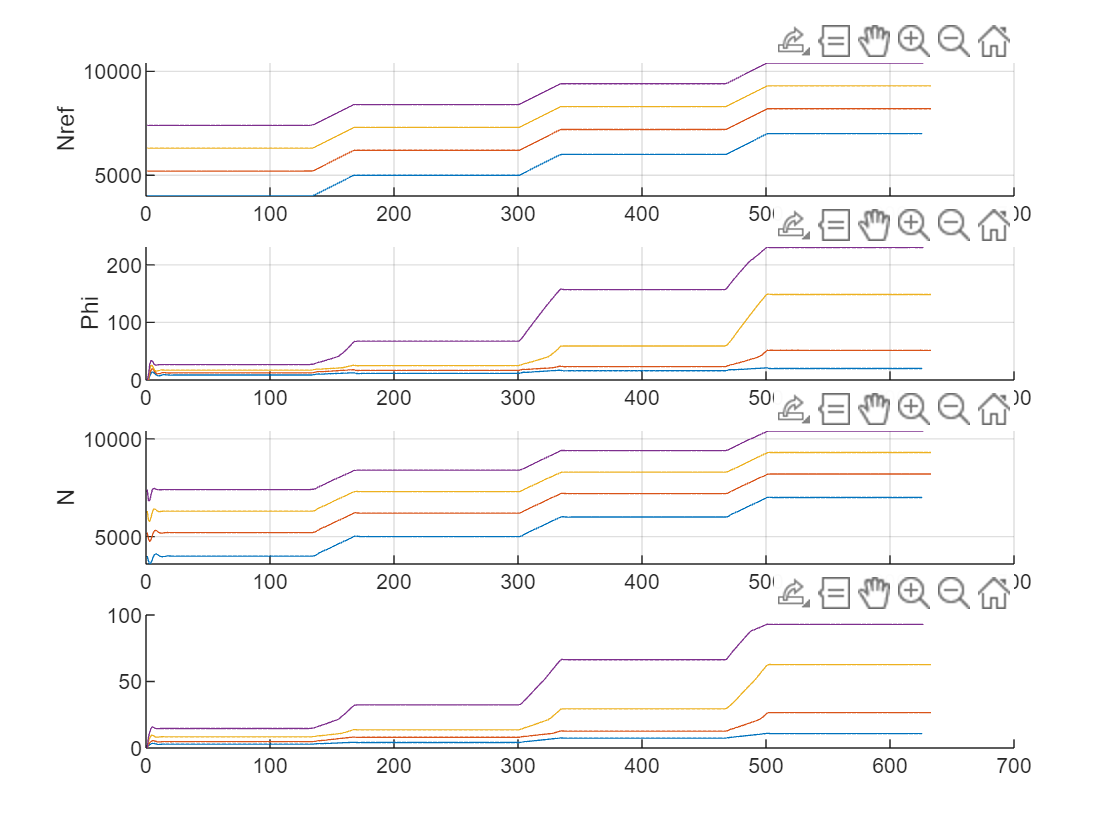

Index exceeds the number of array elements. Index must not exceed 3.

Error in visualizeTrainData (line 23)
    ylabel(ax{ix},signalNames{ix})

visualizeTrainData(trainData(:),signalNames, 'Resampled Data')

## Partition trainning data

trainPercentage = 1; % the percentage of the data that they will be used for training
                       % the rest will be used for test

[dataTrain, dataTest] = trainPartitioning(trainData, trainPercentage);


## Normalize data

You can normalize data by substracting the 

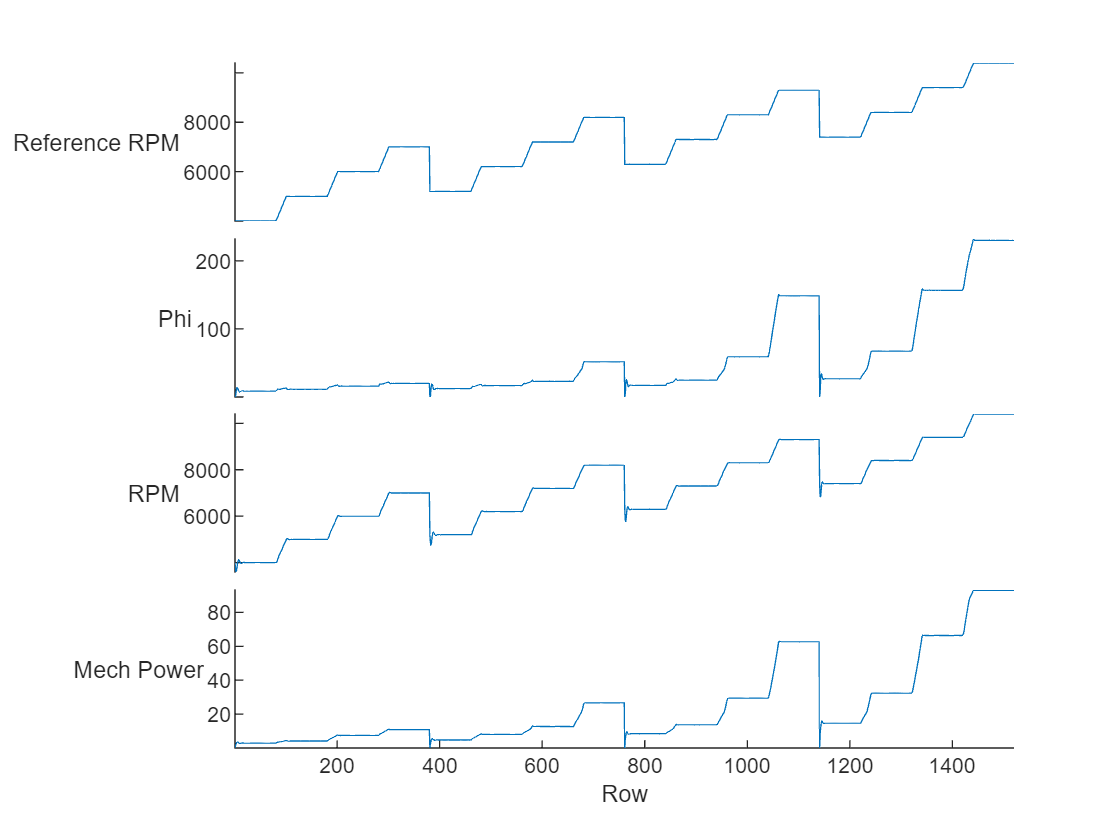

normalize = @(x,mu,sigma) (x - mu) ./ sigma;
dataTrainNorm = normalizeDataMinMax(normalize, dataTrain, meanTrain, stdTrain);

# Define Network Architecture

## Inputs outputs

Define inputs/outputs dimensions

numFeatures = 4;
numResponses = 3;
outStartIdx = 2;
numHiddenUnits = 150;
dropoutProbability = 0.2;

# Train Neural Network

Define the network architecture:

layers = [
    sequenceInputLayer(numFeatures,"Name","input")
    lstmLayer(numHiddenUnits,"Name","lstm","OutputMode","sequence")
    dropoutLayer(dropoutProbability,"Name","drop")
    fullyConnectedLayer(numHiddenUnits,"Name","fc_1")
    reluLayer("Name","relu")
    fullyConnectedLayer(numResponses,"Name","fc_2")
    regressionLayer("Name","regressionoutput")
    ];

Define the trainning options:

opts = trainingOptions("adam",...
    "ExecutionEnvironment","auto",...
    "InitialLearnRate",0.01,...
    "MaxEpochs",1000,...
    "Shuffle","every-epoch",... 
    "LearnRateSchedule","piecewise",...
    "LearnRateDropPeriod",200,...
    "LearnRateDropFactor",0.1,...
    "ValidationFrequency",10,...
    "Plots","training-progress");
    % "ValidationData",{XTestSep,TTestSep},...


Train the network:

Training on single GPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:01 |         1.50 |          1.1 |          0.0100 |
|      50 |          50 |       00:00:03 |         0.15 |      1.1e-02 |          0.0100 |
|     100 |         100 |       00:00:04 |         0.11 |      6.2e-03 |          0.0100 |
|     150 |         150 |       00:00:05 |         0.10 |      4.9e-03 |          0.0100 |
|     200 |         200 |       00:00:07 |         0.09 |      4.1e-03 |          0.0100 |
|     250 |         250 |       00:00:08 |         0.09 |      3.9e-03 |          0.0010 |
|     300 |         300 |       00:00:09 |         0.09 |      3.9

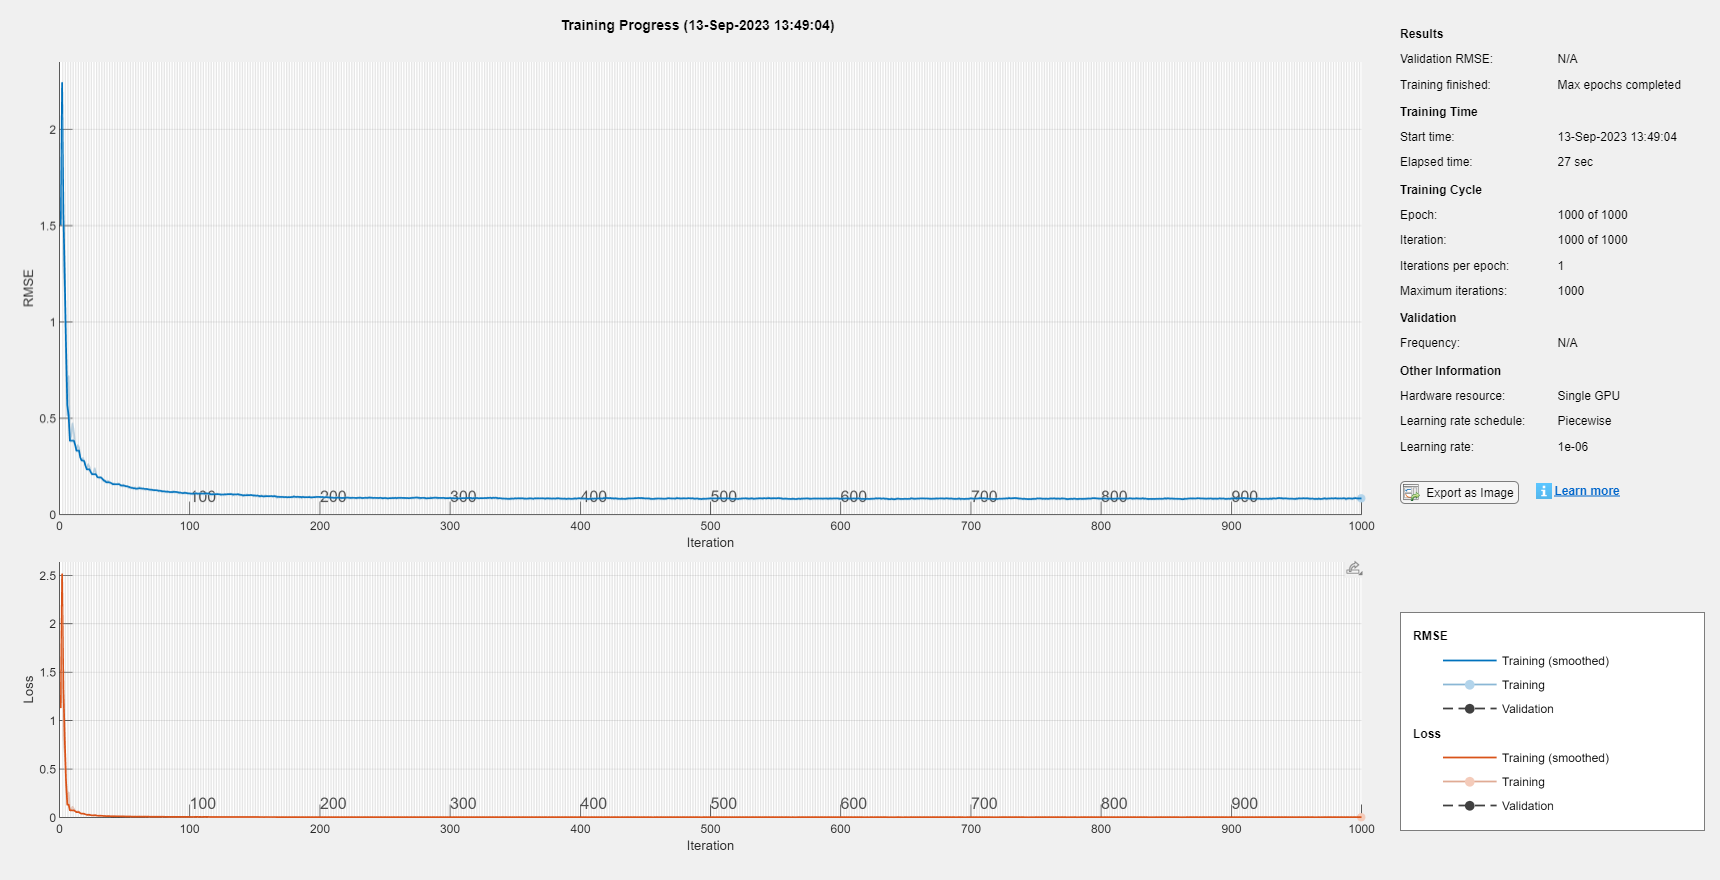

if train
    [net, traininfo] = trainNetwork(XTrainSep,TTrainSep,layers,opts);
    net = resetState(net);
end

Save the network

save(fullfile(proj.RootFolder, 'Demo','braytonLSTMNetThermo'), 'net')

## Check Neural Network response

%% Inspect NN response
% mean(dev{1})
% std(dev{1})
results = getLSTMResponses(XTrainSep, TTrainSep, net)

results = 1×8 cell array
    {6×564 double}    {6×552 double}    {6×534 double}    {6×540 double}    {6×564 double}    {6×598 double}    {6×698 double}    {6×558 double}


% dev = compareResponses(TTrainSep, results, signalNames(outStartIdx:end), 'NN Response');


## Open loop prediction - Update States

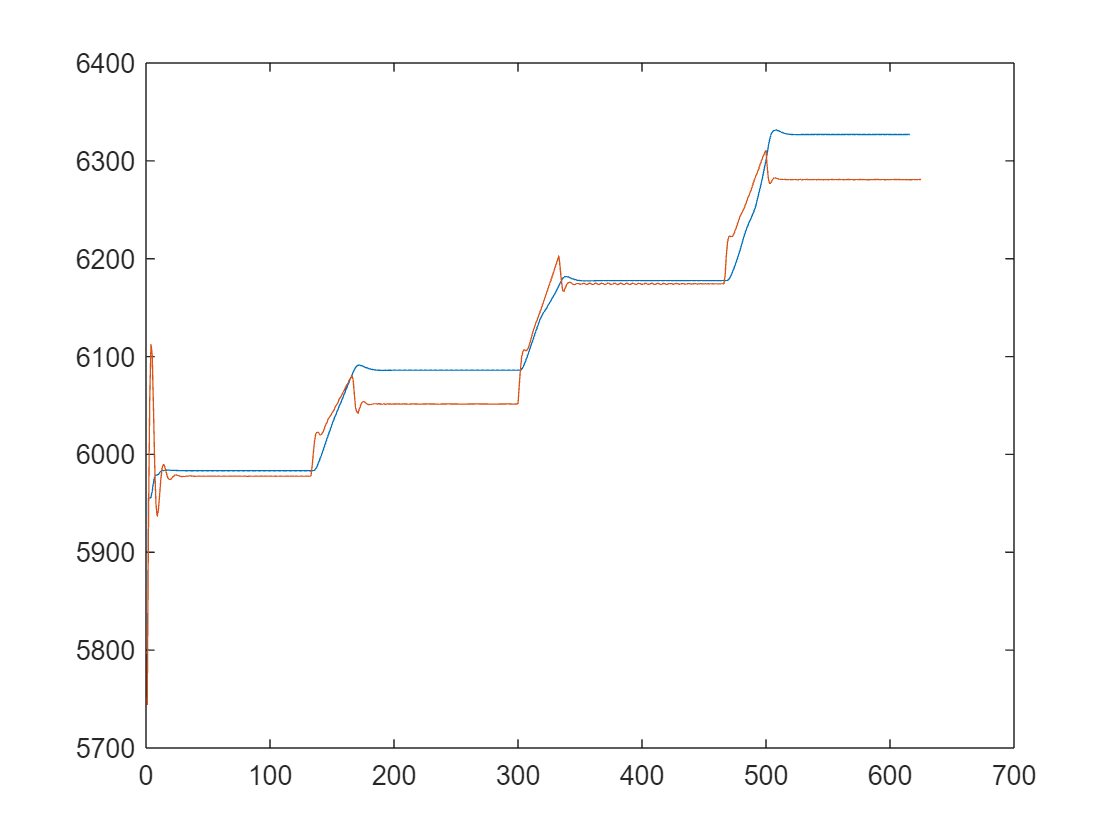

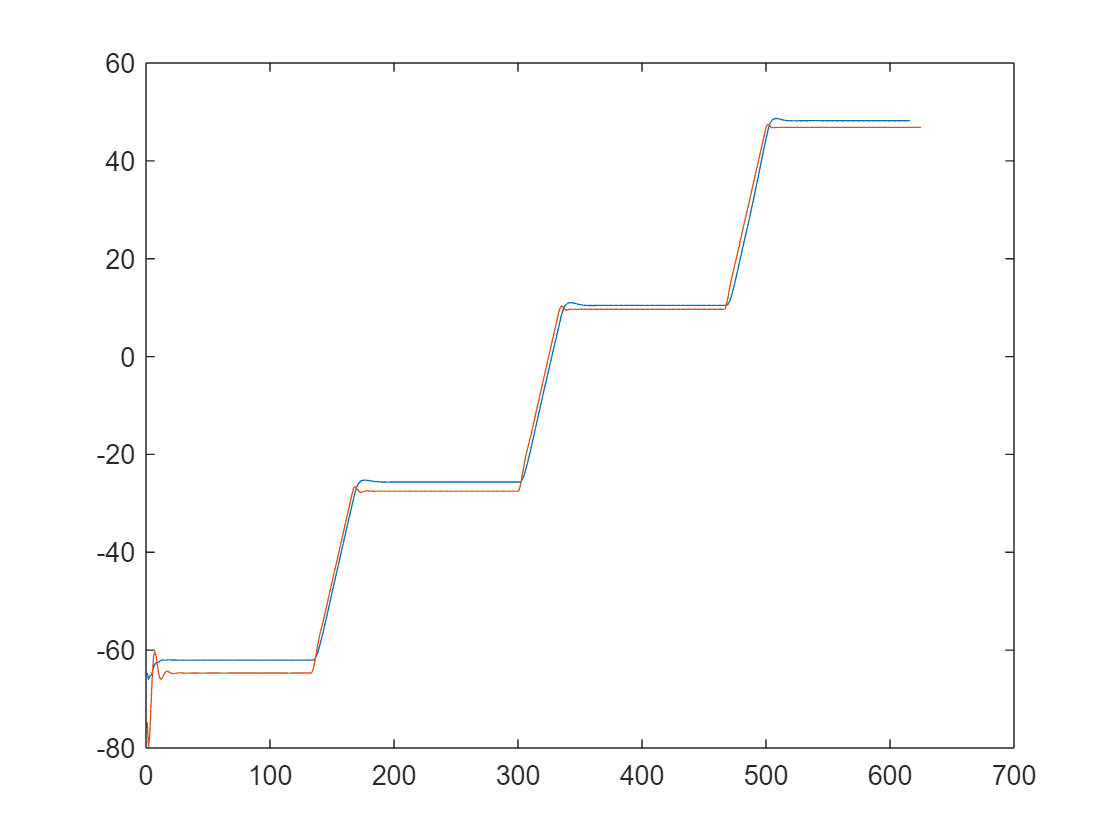

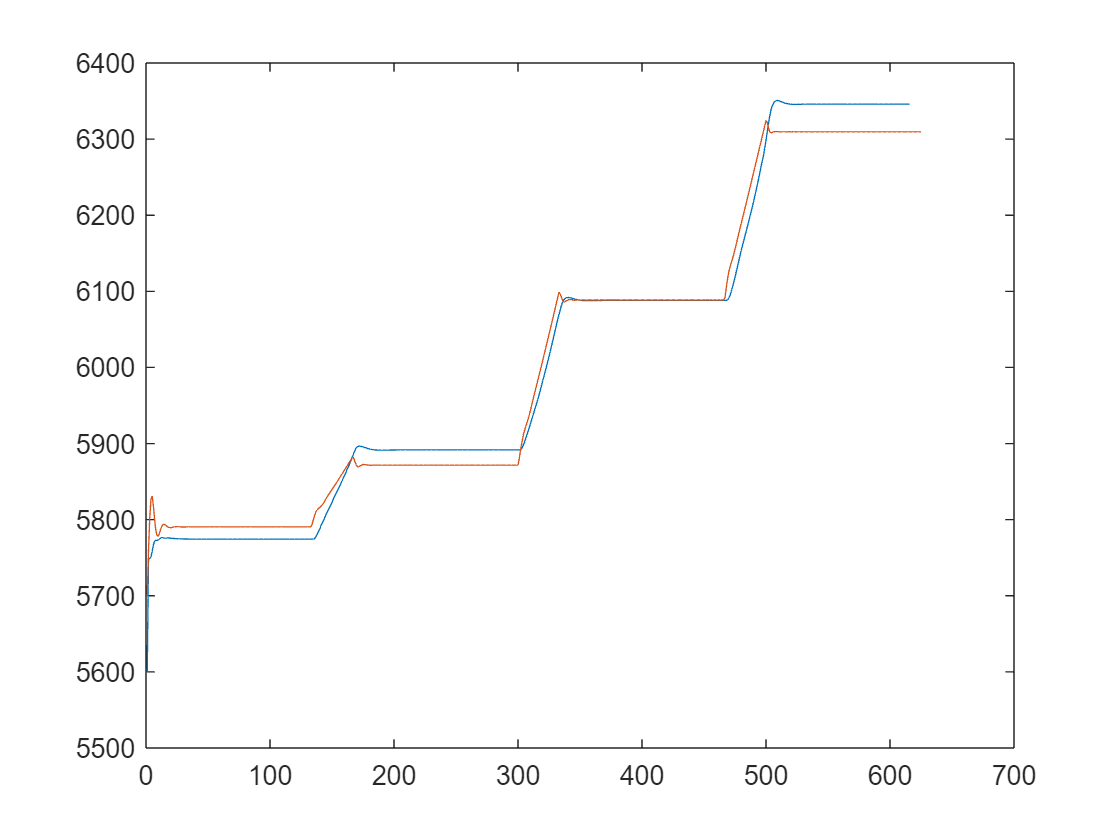

idx = 1;
X = XTrainSep{idx};
TY = TTrainSep{idx};

net = resetState(net);
offset = 9;
[net,~] = predictAndUpdateState(net,X(:,1:offset));

numTimeSteps = size(X,2);
numPredictionTimeSteps = numTimeSteps - offset;
Y = zeros(numResponses,numPredictionTimeSteps);
Y(:,1) = X(2:end,1);
for t = 2:numPredictionTimeSteps
    Xt = [X(1,t-1);Y(:,t-1)];
    [net,Y(:,t)] = predictAndUpdateState(net,Xt);
   hiddenState(t,:) = net.Layers(2,1).HiddenState;
   cellState(t,:) = net.Layers(2,1).CellState;
end

for inspSig=1:numResponses
figure
plot(Y(inspSig,:)'*stdTrain(inspSig)+meanTrain(inspSig))
hold on
plot(TY(inspSig,:)'*stdTrain(inspSig)+meanTrain(inspSig))
hold off
end

## Plot hidden/cell states

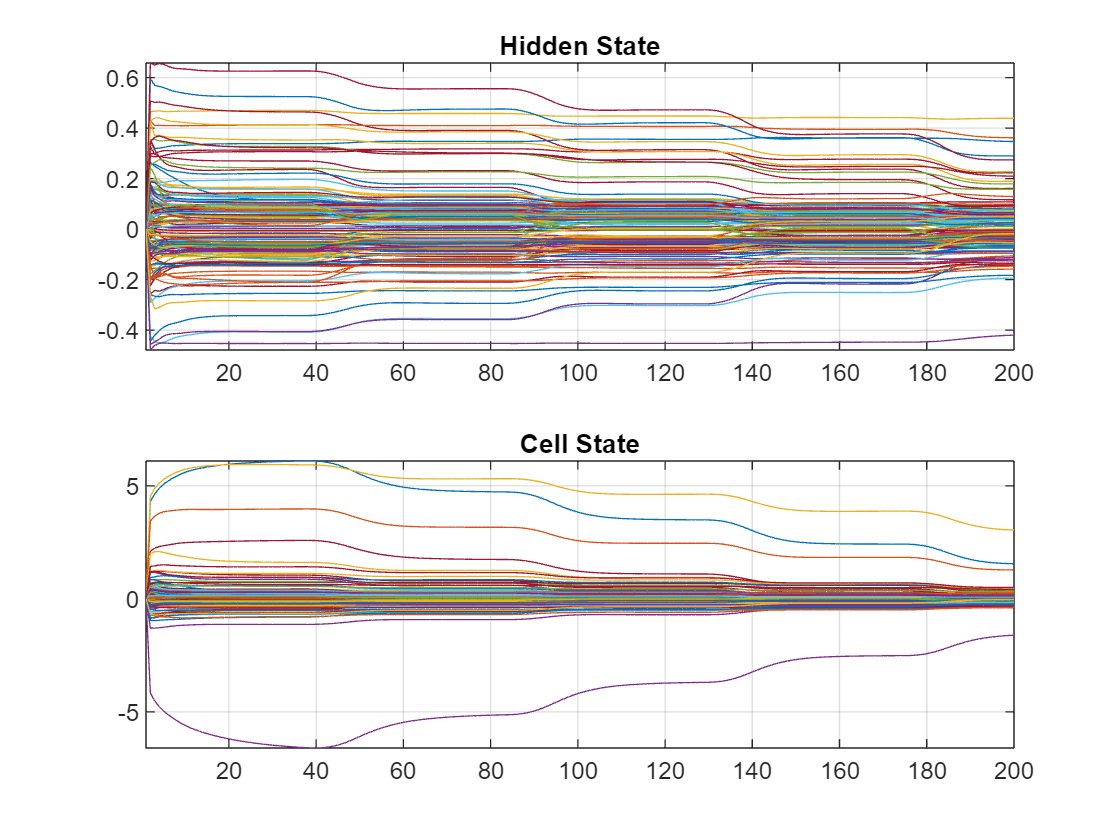

figure
subplot(2,1,1)
plot(hiddenState(1:200,:))
grid on
axis tight
title('Hidden State')
subplot(2,1,2)
plot(cellState(1:200,:))
grid on
axis tight
title('Cell State')

## Simulate ROM model

modelROM = 'brayton_cycle_LSTM_ROM';
clearvars simInROM
scenarioIdx = 1;
testScenario = scenario{scenarioIdx};  
simInROM = Simulink.SimulationInput(modelROM);

% Initialize compressor's RPM with respect to the Simulation scenarios
rpm0 = testScenario.shaftSpeedRef{1}.Values.Data(1);
simInROM = setVariable(simInROM, 'rpm0', rpm0, ...
    'Workspace', modelName);  
simInROM = setVariable(simInROM, 'rpm_setpoint', testScenario.shaftSpeedRef{1}.Values.Data', ...
    'Workspace', modelName);    
simInROM = setVariable(simInROM,'time_setpoint', testScenario.shaftSpeedRef{1}.Values.Time', ...
    'Workspace', modelName);


## Simulate ROM

outROM = sim(simInROM);

Error due to multiple causes.

Caused by:
    Error using Simulink.Simulation.internal.DesktopSimHelper
    Simulink cannot determine sizes and/or types of the outputs for block 'brayton_cycle_LSTM_ROM/Brayton ROM/Stateful Predict2/MLFB' due to errors in the block body, or limitations of the underlying analysis. The errors might be inaccurate. Fix the indicated errors, or explicitly specify sizes and/or types for all block outputs.
    
    
    Error using Simulink.Simulation.internal.DesktopSimHelper
    Error in port widths or dimensions. 'Output Port 1' of 'brayton_cycle_LSTM_ROM/Brayton ROM/Stateful Predict2/MLFB/in_1' 

## Compare ROM with initial model


import matlab.unittest.TestCase
import Simulink.sdi.constraints.MatchesSignal
import Simulink.sdi.constraints.MatchesSignalOptions
% Create a test case:
testCase = TestCase.forInteractiveUse;    

% Set accepted tolerance
relTol = 1e-1;

% Map log signals
dic = {};
dic{1} = 2;
dic{2} = 1;
dic{3} = 4;

% Compare different signals between ROM LSTM model and original model.
for ix=1:outROM.logsout.numElements-1
        testCase.verifyThat(outROM.logsout{ix},MatchesSignal(out(scenarioIdx).logsout{dic{ix}},'RelTol',1e-4))
end


## Wavelet analysis

cwt(XTrainSep{1}(5,:),1)


## Update parameters

open_system('gasTurbine_ROM')

hws = get_param('gasTurbine_ROM', 'modelworkspace');

hws.assignin('RPM_refMean', meanTrain(1));
hws.assignin('phiMean', meanTrain(2));
hws.assignin('rpmMean', meanTrain(3));
hws.assignin('powerMean', meanTrain(4));
% hws.assignin('t3Mean', meanTrain(5));

Index exceeds the number of array elements. Index must not exceed 4.


hws.assignin('RPM_refStd', stdTrain(1));
hws.assignin('phiStd', stdTrain(2));
hws.assignin('rpmStd', stdTrain(3));
hws.assignin('powerStd', stdTrain(4));
% hws.assignin('t3Std', stdTrain(5));


hws.assignin('samplTime', resampleTimeStep);
